# ACM 11: Week 6 Exercise 3 - Gauss-Legendre quadrature

**(0) Names of all group members: Kyle McGraw**

## Gauss-Legendre Quadrature

Where before we assumed *N* fixed equispaced quadrature points, in this exercise we allow for a nonuniform grid of points. We will explore convergence uisng Gaussian-Legendre quadrature for numerical integration of the function:


$$f(x)=\frac{1}{\sqrt{2\pi}}\exp(-x^2/2) + \exp(3x)$$


Again, the code block below sets up the function to be integrated, bounds for integration, number of quadrature points, and the exact value for comparison.

% function to be integrated
f = @(x) 1/sqrt(2*pi)*exp(-x.^2/2)+exp(3*x); 

% bounds
a = -1.5; b = 1.5; 

% quadrature points
N = 50;

% exact integral for comparison
exact =  integral(f,a,b)

exact = 30.8684

Gauss-Legendre quadrature approximates integrals on the interval [-1,1] as follows:

$\int_{-1}^1 f(x)\,\text{d}x \approx \sum_{i=1}^N w_i f(x_i)$,

where the weights and points used in the scheme are output by the provided function qrule.m. 

**(1) Implement "gauss_legendre" at the bottom of this live script using the provided function "qrule.m", which outputs quadrature points and weights for the interval [-1,1]. You will have to transform the output for the interval [a,b] as follows:**


$$\tilde x_i = a + \frac{b-a}2(x_i+1), \qquad \tilde w_i = \frac{b-a}2w_i$$


**(2) Use your function to compute I_gauss in the code block below with N=50 points. Your error should be very low.**

I_gauss = gauss_legendre(f,a,b,N); % fill in and implement gauss_legendre.m
I_gauss

I_gauss = 30.8684

**(3) Compute the Gauss-Legendre approximation for different values of *****N***** and plot its absolute error to observe the rate of convergence.**

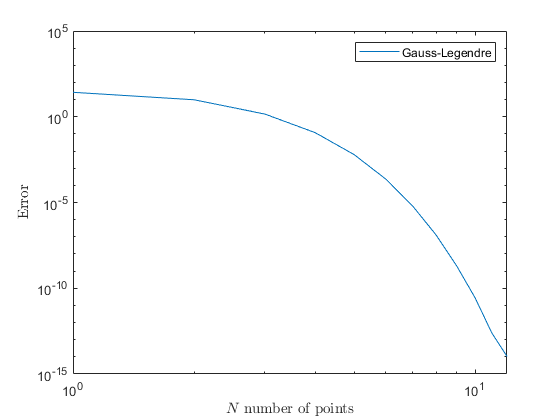

% Convergence study
N = 1:12;
errgauss = zeros(length(N),1);

for j=1:length(N) 
    x = linspace(a,b,N(j)); % integration points
    fval = f(x); % function values
    
    % Gauss-Legendre
    I_gauss = gauss_legendre(f,a,b,N(j)); % fill in
    errgauss(j) = abs(exact-I_gauss); % fill in
end

loglog(N,errgauss);
xlabel('$N$ number of points','interpreter','latex'); 
ylabel('Error','interpreter','latex'); 
legend('Gauss-Legendre'); 

**(4) Comment on what you observed from the plots. How does Gauss-Legendre convergence compare to what you saw for the Newton-Cotes methods?**

Error doesn't decay at a linear rate and drops off much quicker as the points increases.

function I = gauss_legendre(f,a,b,N)

    [x,w] = qrule(N); % this will give you the points and weights for [-1, 1]
    
    xtilde = a+(b-a)/2*(x+1); % TODO: transform for [a,b]
    wtilde = (b-a)/2*w; % TODO: transform for [a,b]

    I = sum(wtilde.*f(xtilde)); % fill in

end